clc
clear


$$min \sum \alpha + \sum \beta+\sum\gamma\\
s.t\quad A_T\textbf{x}\ge 85-\alpha\\
\qquad A_C\textbf{x}\le45+\beta\\
\qquad A_N\textbf{x}\le+\gamma\\
\qquad \textbf{x},\alpha,\beta,\gamma\ge0$$



$$min \sum_{i=1}^p \alpha_i + \sum_{i=1}^q \beta_i+\sum_{i=1}^r\gamma_i\\
s.t\quad \sum_{j=1}^n t_{ij}x_j\ge 85-\alpha_i\quad i=1,2,...,p\\
\qquad \sum_{j=1}^n c_{ij}x_j\le45+\beta_i\quad i=1,2,...,q\\
\qquad \sum_{j=1}^n n_{ij}x_j\le0+\gamma_i\quad  i=1,2,...,r\\
\qquad x, \alpha,\beta,\gamma\ge0
$$



$$A_T=\{t_{ij}\}\quad
A_C=\{c_{ij}\}\quad
A_N=\{n_{ij}\}\quad
$$


type_mat = Types;
tumor_ind = find(type_mat==1);
criti_ind = find(type_mat==2);
normal_ind = find(type_mat==3);

dose_mat = DoseMatrix;
AT = dose_mat(tumor_ind,:);
AC = dose_mat(criti_ind,:);
AN = dose_mat(normal_ind,:);

A = [-AT; AC; AN];

[row_at, ~] = size(AT);
atb = -85*ones(row_at, 1);
[row_ac, ~] = size(AC);
acb = 45*ones(row_ac, 1);
[row_an, ~] = size(AN);
anb = zeros(row_an, 1);

b = [atb; acb; anb];

co = eye(row_at+row_ac+row_an);
co = [co(1:9, :); -1*co(10:1055 , :)];

A = [A, co];

[x,fval,exitflag,output,lambda] = linprog([zeros(1, 594), 5*ones(1, row_at), 4*ones(1, row_ac), 1*ones(1, row_an)],...
    A, b, [], [], zeros(1, 594+row_at+row_ac+row_an))


Optimal solution found.



x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


fval = 1.1974e+04

exitflag = 1

output = struct with fields:
         iterations: 29
    constrviolation: 4.2633e-14
            message: 'Optimal solution found.'
          algorithm: 'dual-simplex'
      firstorderopt: 2.0986e-12


lambda = struct with fields:
      lower: [1649×1 double]
      upper: [1649×1 double]
      eqlin: []
    ineqlin: [1055×1 double]


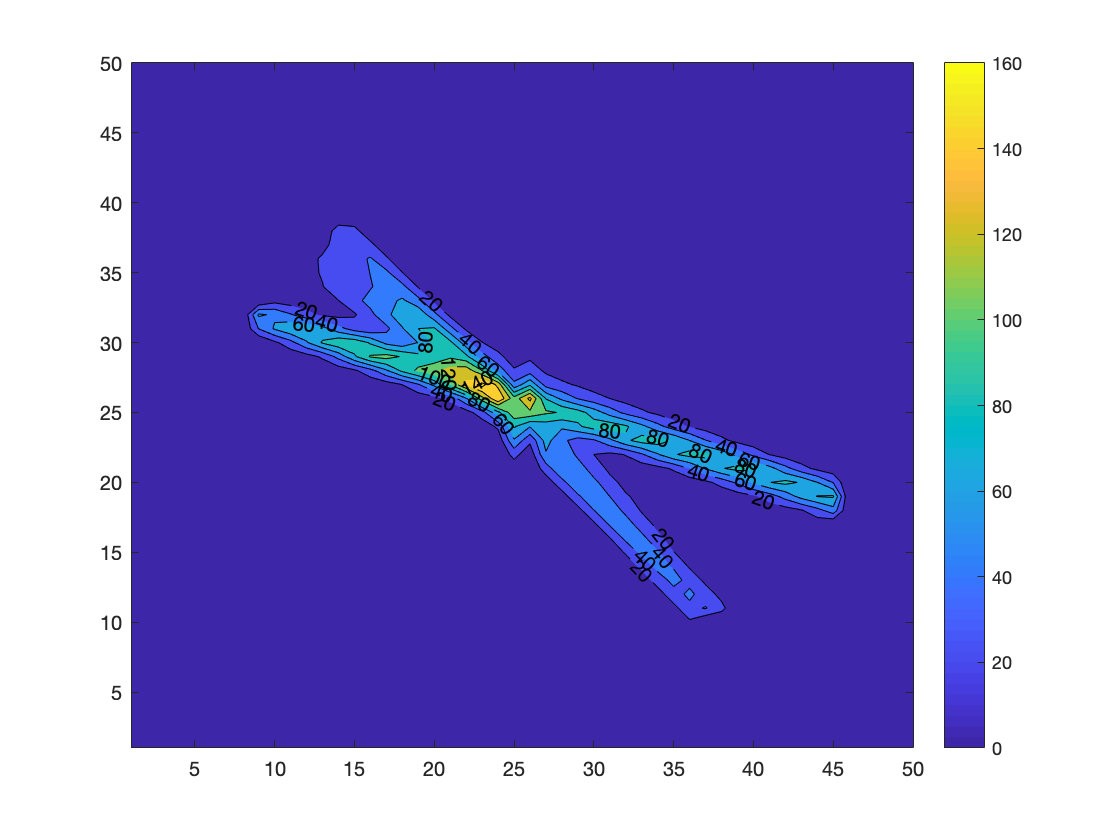

dose = dose_mat*x(1:594);
dose = reshape(dose, 50, 50);
contourf(dose, 'ShowText','on')
colorbar

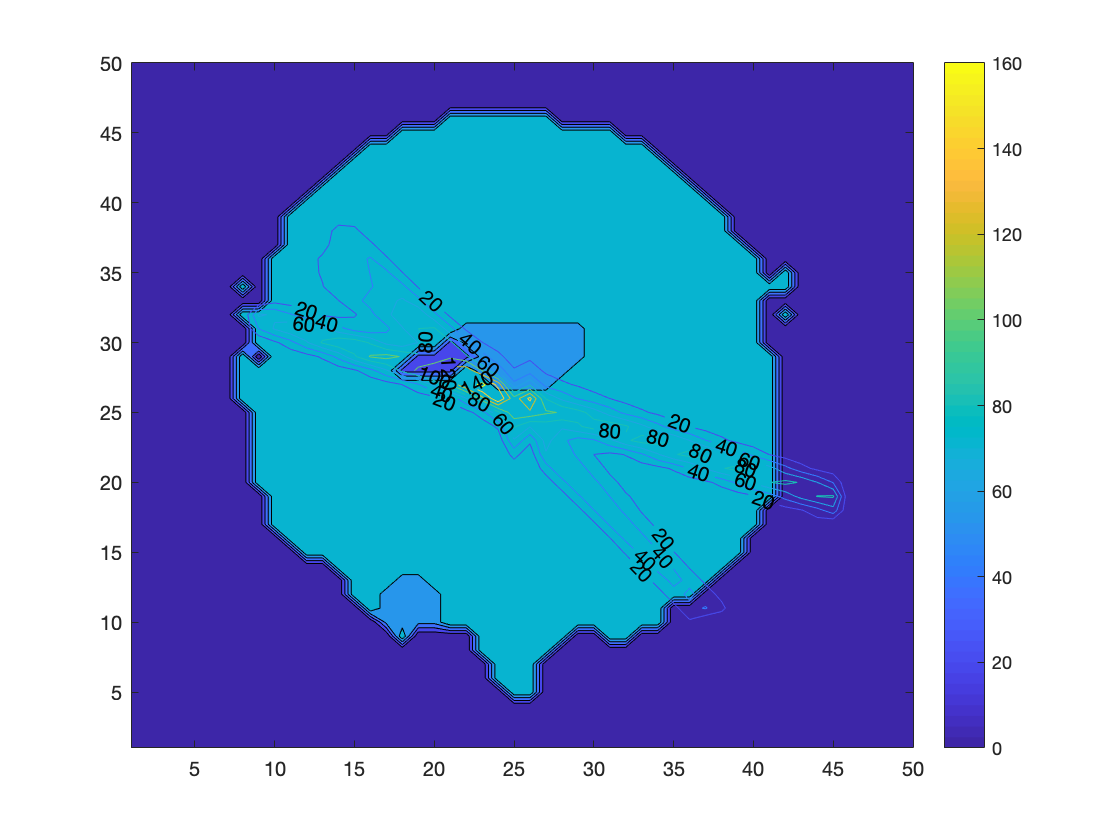

contourf(30*(type_mat), 4);
hold on
contour(dose, 'ShowText','on')
colorbar
hold off